# Lab 3

Ross Smyth

clear, clc, close all
addpath ADSP_ToolBox\

## Project 1: Convolution Basics

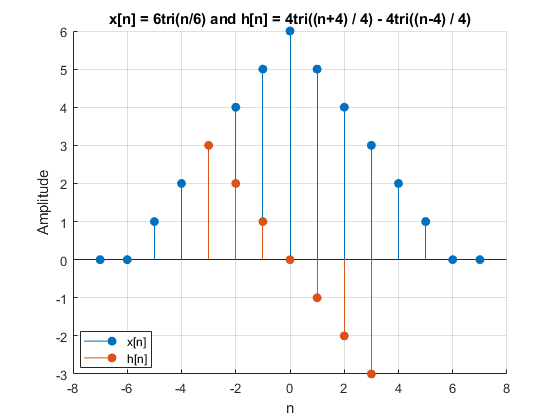

% a
nx = -7:7;
x = 6 * tri(nx / 6);

nh = -3:3;
h = 4 * tri((nh + 4) / 4) - 4 * tri((nh - 4) / 4);

figure()
hold on
stem(nx, x, 'filled')
stem(nh, h, 'filled')

xlabel('n')
ylabel('Amplitude')
title('x[n] = 6tri(n/6) and h[n] = 4tri((n+4) / 4) - 4tri((n-4) / 4)')
legend({'x[n]', 'h[n]'}, 'Location',"best")
grid
hold off

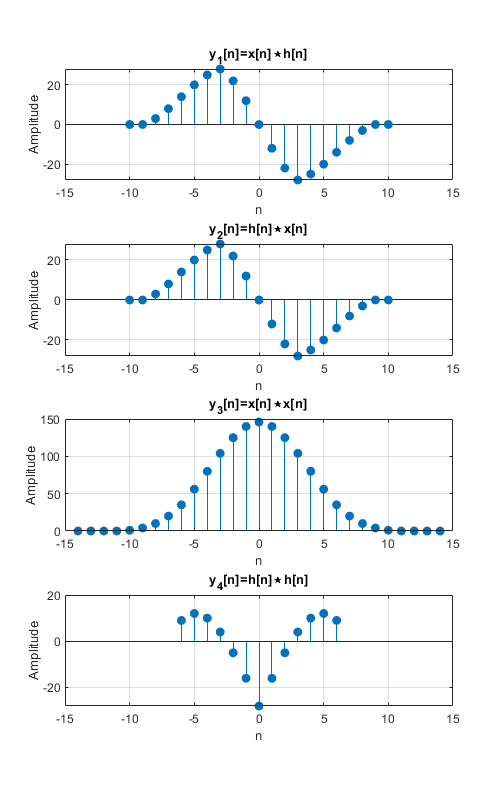

% b
y1 = conv(x, h);
y2 = conv(h, x);
y3 = conv(x, x);
y4 = conv(h, h);

% c
figure()
hold on

subplot(4, 1, 1)
stem(-10:10, y1, 'filled')
ylabel('Amplitude')
xlabel('n')
title('y_1[n]=x[n]⋆h[n]')
grid
xlim([-15, 15])

subplot(4, 1, 2)
stem(-10:10, y2, 'filled')
ylabel('Amplitude')
xlabel('n')
title('y_2[n]=h[n]⋆x[n]')
grid
xlim([-15, 15])

subplot(4, 1, 3)
stem(-14:14, y3, 'filled')
ylabel('Amplitude')
xlabel('n')
title('y_3[n]=x[n]⋆x[n]')
grid
xlim([-15, 15])

subplot(4, 1, 4)
stem(-6:6, y4, 'filled')
ylabel('Amplitude')
xlabel('n')
title('y_4[n]=h[n]⋆h[n]')
grid
xlim([-15, 15])

set(gcf, 'Position', [0, 0, 500, 800])
hold off

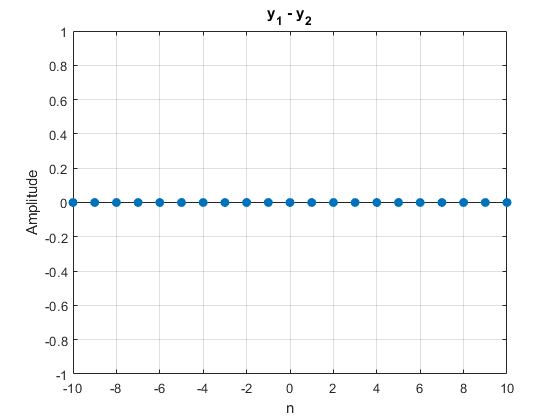

% d
figure()
stem(-10:10, y1-y2, 'filled')
title('y_1 - y_2')
ylabel('Amplitude')
xlabel('n')
grid

all((y1-y2) == 0) % Confirmed

ans = logical
   1


% e
len_prop = length(x) + length(h) - 1; % The theoretical length
len_prop == length(y1) % Confirmed

ans = logical
   1


% f
sum_prop = sum(x) * sum(x); % Theoretical sum
sum(y3) == sum_prop % Confirmed

ans = logical
   1


### g: Symmetry types

- If both convolved signals are evenly symmetric then the convolved signal will be even, as seen in the result of x[n]⋆x[n].

- If both signals are oddly symmetric then the output signal is also evenly symmetric as seen in the figure of $y_4$.

- If one signal is odd and the other signal then the out will be oddly symmetric. This can be seen for the plot sof $y_1$ and $y_2$.

## Project 2: Response to Periodic Inputs

clc, clear, close all

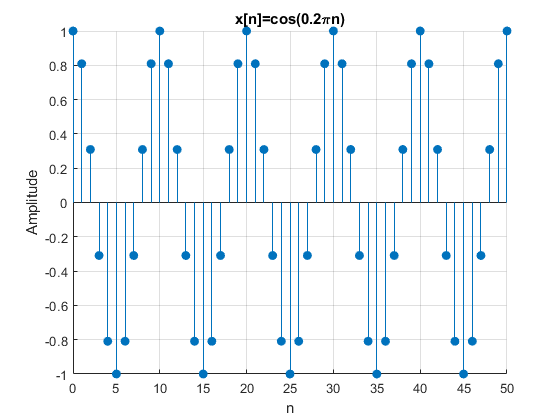

% a
n = 0:50;
x = cos(0.2 * pi * n);
h = 1:8;

figure()
hold on
stem(n, x, "filled")

ylabel('Amplitude')
xlabel('n')
title('x[n]=cos(0.2\pin)')
grid
hold off

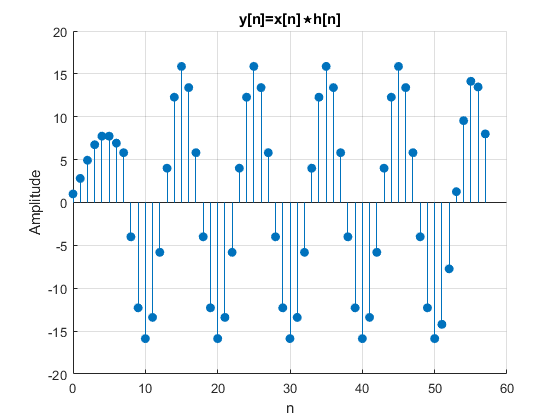

% b
y = conv(x, h);

figure()
hold on
stem(0:57, y, "filled")

ylabel('Amplitude')
xlabel('n')
title('y[n]=x[n]⋆h[n]')
grid
hold off

% c

figure()
hold on
subplot(2, 1, 1)
stem(n, x, "filled")

ylabel('Amplitude')
xlabel('n')
title('x[n]=cos(0.2\pin)')
grid
xlim([0, 60])

subplot(2, 1, 2)
stem(0:57, y, "filled")

ylabel('Amplitude')
xlabel('n')
title('y[n]=x[n]⋆h[n]')
grid
xlim([0 60])

set(gcf, 'Position', [0, 0, 500, 600])
hold off

### d: Period

By inspection the period of x[n] is 10 samples.

### e: Response periodicity

Ignoring the startup and end transients, the reponse is periodic as seen by the above plot.

### f: Response period

By inspection of the response plot, the period of the response is also 10 samples. This is the same as the input's period.

## Project 3: Periodic Convolution

clear, clc, close all

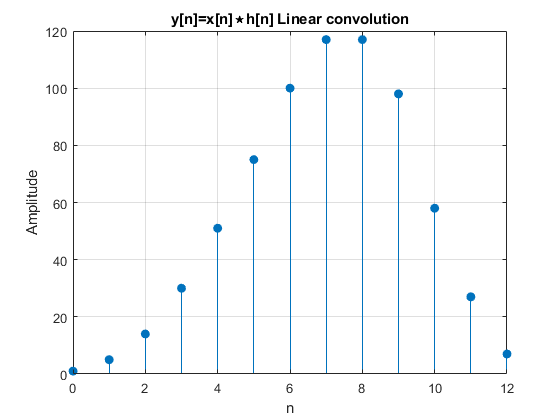

% a
x = [1, 3, 5, 7, 5, 3, 1];
h = 1:7;

y = conv(x, h);

figure()
stem(0:12, y, "filled") % Assuming that the first is the zeroth index in both signals.

ylabel('Amplitude')
xlabel('n')
title('y[n]=x[n]⋆h[n] Linear convolution')
grid

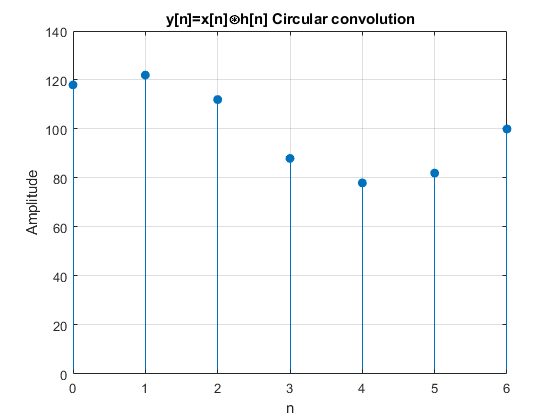

% b
yp = convp(x, h);

figure()
stem(0:6, yp, "filled") % Assuming that the first is the zeroth index in both signals.

ylabel('Amplitude')
xlabel('n')
title('y[n]=x[n]⊛h[n] Circular convolution')
grid

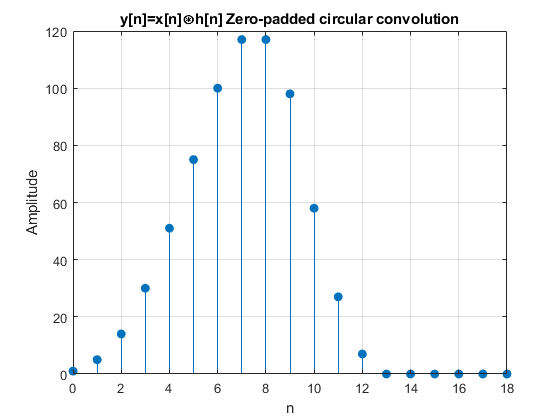

% c
needed = length(x) + length(y) - 1;

x_pad = [x, zeros([1, needed - length(x)])];
h_pad = [h, zeros([1, needed - length(h)])];

y_circ = convp(x_pad, h_pad);

figure()
stem(0:18, y_circ, "filled") % Assuming that the first is the zeroth index in both signals.

ylabel('Amplitude')
xlabel('n')
title('y[n]=x[n]⊛h[n] Zero-padded circular convolution')
grid

### d: Compare results of (a), (b), and (c)

Obviously looking at the results of part (a) and part (c), they are equivalent. There are some zeros padded to the right of the results of (c), but those are implicitly there in the output of (a) as well, just not seen.

The relationship between the linear and circular convolution allows for linear convolution to be carried out in the frequency domain. One assumption when finding the DFT of a signal is that it is periodic, but not all signals are. If one were to folow the convolution theorm blindly and multiply the DFT of the signals, they would get the circular convolution of the signals due to this assumption. If zero-padded though as seen above, this circular convolution will result in the proper linear convolution.

## Project 4: Filtering of Chirp Signal

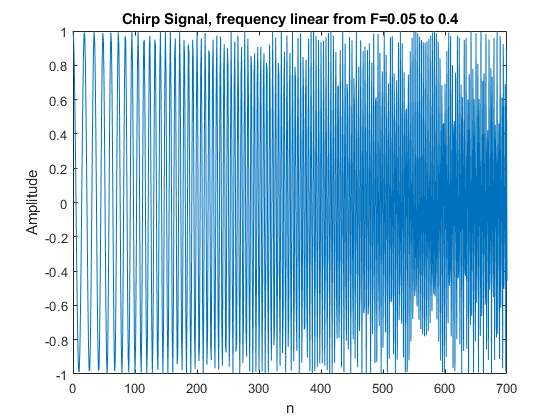

clear, clc, close all
% a
load("chirp_sig.mat") % Exported to .mat file for automation.

figure()
plot(n, x)
xlabel('n')
ylabel('Amplitude')
title('Chirp Signal, frequency linear from F=0.05 to 0.4')

### b: Spectrum of x

By inspecting the PSD estimate, the correct range of frequencies is covered, though near 0.05 and 0.04 the power is much lower.

With the given samples of 701, no other method is able to be used. I adjusted it to 700 samples, which is even, to analyze the other methods. The time-freq spectrum doesn't change between an yof the methods, but the power spectral density estimate does. The Welch method has a much smoother PSD compared to the Periodogram, which means that it is likely the power of the signal is much more evenly distributed each frequency with that method. Blackman/Tukey is simlar but has some "ears" on the right and left hand sides of the signal.

### c: time-freq spectrum

Looks linear to me.

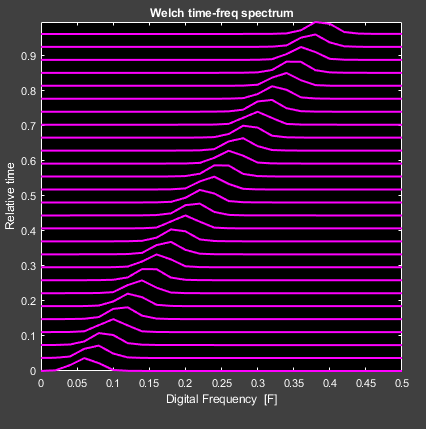

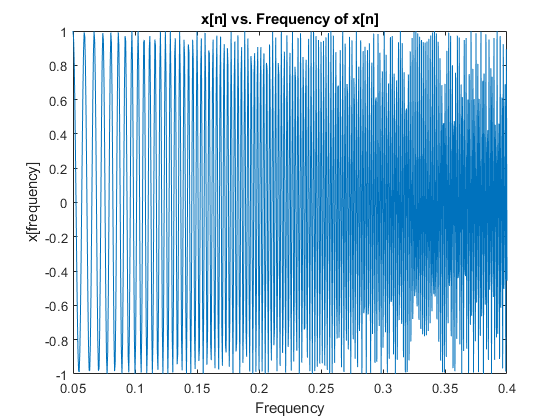

% d

m = (0.4 - 0.05) / 700; % m*x+b
F = 0.05 + (0:700) * m;

figure()
plot(F, x)
xlabel('Frequency')
ylabel('x[frequency]')
title('x[n] vs. Frequency of x[n]')

Looks the same, so it is linear with frequency.

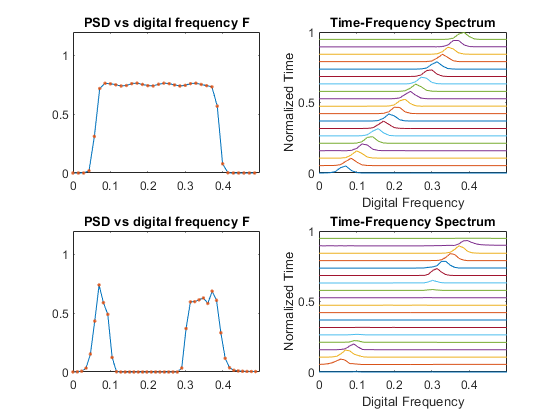

% e
n  = -80:80;
h1 = udelta(n) - 0.4 * cos(0.4 * pi * n) .* sinc(0.2 * n);

y1 = conv(h1, x); % Response to chirp.

figure()
subplot(2, 2, 1)
psdwelch(x);
axis([0 0.5 0 1.2])

subplot(2, 2, 2)
timefreq(x)

subplot(2, 2, 3)
psdwelch(y1);
axis([0 0.5 0 1.2])

subplot(2, 2, 4)
timefreq(y1);

### f: Identifying filter type from plots

Looking at the power spectral desnity plots, it is extremly easy to tell what type of filter $h_1 \left\lbrack n\right\rbrack$ is. It is a band-stop filter, as the lower frequencies are conserved and the higher frequencies are conserved, but the frequencies between about 0.1 and 0.3 have near zero power.

Similarly the time-frequency spectrum show the same effect. Since the frequency varies linearly with time, the times when $x\left\lbrack n\right\rbrack$ is in the frequencies being filtered out, there are no frequencies present as the signal is near zero. This makes it clear what type of filter $h_1 \left\lbrack n\right\rbrack$ is.

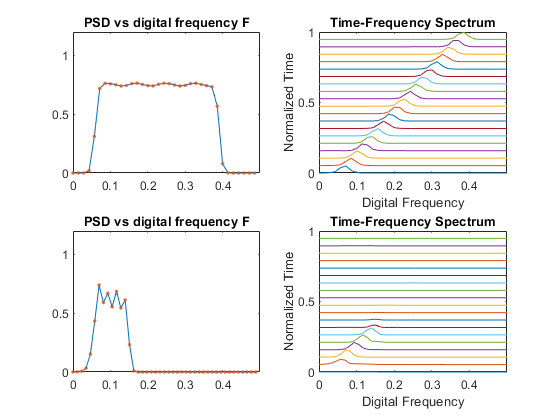

% g
h2 = 0.3 * sinc(0.3 * n);

y2 = conv(x, h2);

figure()
subplot(2, 2, 1)
psdwelch(x);
axis([0 0.5 0 1.2])

subplot(2, 2, 2)
timefreq(x)

subplot(2, 2, 3)
psdwelch(y2);
axis([0 0.5 0 1.2])

subplot(2, 2, 4)
timefreq(y2);

By inspecting the above plots, it is clear that this filter is a high-pass filter. The power spectral density plot above shows that above $F=0\ldotp 15$, the power of those frequencies is near zero, while before that the power is almost conserved from the input signal.

### h: Explain process of identifying filter

Because the power of the frequencies above $F=0\ldotp 15$ is near zero, that makes it extremly clear that the filter is a high-pass filter. Similarly the time-frequency plot shows that after the time in which the frequencies above $F=0\ldotp 15$ are hit, the signal has no clear dominant frequency. This is because the signal is almost completely attenuated because it is supposed to consistent of those frequencies wholly after that time.